# HW 5 Solution

## Starter Code

Run starter code.

starter_code() ;

## Problem 1a

The 3-link dynamics for this problem are given by:


$$D(q) \ddot q + C(q) \dot q + G(q) = B(q) u + J_{st}^T(q) F_{st}$$


Here, $F_{st}$ is the ground reaction force that enforces that the stance foot doesn't move.  This force is dependent on both the state $s$ and the input $u$.  We can break this into two components as follows:


$$F_{st} = F_{st}^{no-u} + F_{st}^u~u$$


The first term does not depend on $u$ while the second term depends linearly on $u$.  These terms can be computed as:

$F_{st}^u = \frac{\partial F_{st}}{u}$, and $F_{st}^{no-u} = F_{st} - F_{st}^u~u$.

With this information, we can compute the vector fields $f(s)$ and $g(s)$.

%% [Part 1a] Compute the f and g vectors
% Fill up this

% Split FSt into 2 components: 1. which depends on u and 2. which does not depend on u
% Note: FSt is linear in u

Fst_u = jacobian(FSt, u) ; % FSt = Fst_u*u + (Fst - Fst_u*u)
Fst_u = simplify(Fst_u) ;

Fst_nu = FSt - Fst_u*u ; % Fst_nu = (Fst - Fst_u*u)
Fst_nu = simplify(Fst_nu) ;


% Compute vector fields
fvec = [dq ;
        inv(D)*(-C*dq - G + JSt'*Fst_nu)];
fvec = simplify(fvec);

gvec = [zeros(NDof, length(u));
          inv(D)*(B + JSt'*Fst_u)];
gvec = simplify(gvec);

% Write out files
matlabFunction(fvec, 'File', 'gen/fvec_gen', 'Vars', {s});
matlabFunction(gvec, 'File', 'gen/gvec_gen', 'Vars', {s});

## Problem 1b

Let's define the relative and absolute generalized coordinates as below:

$q=\left\lbrack \begin{array}{c}
x\\
y\\
q_{1\;} \\
q_2 \\
q_3 
\end{array}\right\rbrack ,q_{\textrm{abs}} =\left\lbrack \begin{array}{c}
x\\
y\\
\theta {\;}_{1\;} \\
\theta {\;}_2 \\
\theta_{\;3} 
\end{array}\right\rbrack$, then these can be related as $q_{abs} = T q + d$.  The matrix $T$ and vector $d$ are as given.  The outputs can be computed based on this.

% Create absolute generalized coordinates
q_abs = T*q + d;

% Create symbolic variable needed for defining output
syms th3d real

% Define Output
y = [q_abs(2+3) - th3d;
     q_abs(2+2) + q_abs(2+1)];

% write out file
matlabFunction(y, 'File', 'gen/y_gen', 'Vars', {s, th3d});

## Problem 1c

The Lie derivatives can be computed based on the code below:

% Define Lie Derivatives
Lfy = jacobian(y, s)*fvec;
Lf2y = jacobian(Lfy, s)*fvec;
LgLfy = jacobian(Lfy, s)*gvec;

% Write out files
matlabFunction(Lfy, 'File', 'gen/Lfy_gen', 'Vars', {s});
matlabFunction(Lf2y, 'File', 'gen/Lf2y_gen', 'Vars', {s});
matlabFunction(LgLfy, 'File', 'gen/LgLfy_gen', 'Vars', {s});

## Problem 1d

The relabelling matrix $R$ swaps the stance and swing legs.  This is computed in the following code:

params.R = [1, 0, 0, 0, 0;
            0, 1, 0, 0, 0;
            0, 0, 0, 1, 0;
            0, 0, 1, 0, 0;
            0, 0, 0, 0, 1];

## Problem 2a

We will create the code to implement the provided controller as well as the simulator to simulate multiple steps of walking.  We will then output the required plots.

Set Parameters:

% Set constant parameters
params.th3d = pi/6 ;
params.eps = 0.1 ;
params.a = 0.9 ;
params.th1d = pi/8 ;
params.T = T ;
params.d = d ;
params.mu = 0.8 ; % Coefficient of friction

Simulate Multiple Steps:

% Set constants
odeOpts = odeset('Events', @three_link_event);
t_sol = [] ; x_sol = [] ;
tspan = [0 3] ;
Nsteps = 5 ;
x0 = [-0.3827, 0.9239, 2.2253, 3.0107, 0.5236, 0.8653, 0.3584, -1.0957, -2.3078, 2.0323]' ;

% Simulate multiple steps
for i = 1:Nsteps
    % Continuous time dynamics
    [t, x] = ode45(@three_link_dynamics, tspan, x0, odeOpts, params);

    % Impact Map
    qminus = x(end, 1:5)';
    dqminus = x(end, 6:end)';
    qPlus = params.R*qminus;
    dqPlus = params.R*dqPlus_gen([qminus;dqminus]);

    % Reinitalize for next step
    x0 = [qPlus;dqPlus];
    tspan = t(end) + [0 3] ;

    % Save state trajectory
    t_sol = [t_sol; t];
    x_sol = [x_sol; x];
end

% animateThreeLink(t_sol, x_sol)

Generate Plots

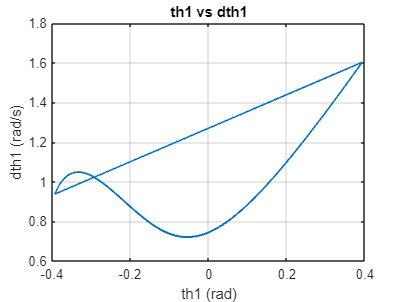

% Extract data for plots
x_th_sol = [] ;
u_sol = [] ;
FSt_sol = [] ;
for j=1:length(t_sol)
    x_th_sol(j,:) = [params.T*x_sol(j,1:5)' + params.d;
                     params.T*x_sol(j,6:end)']' ;
    u_sol(j,:) = three_link_io_control(x_sol(j,:)', params)' ;
    FSt_sol(j,:) = Fst_gen(x_sol(j,:)', u_sol(j,:)') ;
end

% Plot th1 vs dth1
% figure ; plot(x_th_sol(:,2+1), x_th_sol(:,5+2+1)) ;
%     xlabel('th1 (rad)') ; ylabel('dth1 (rad/s)') ; title('th1 vs dth1') ; grid

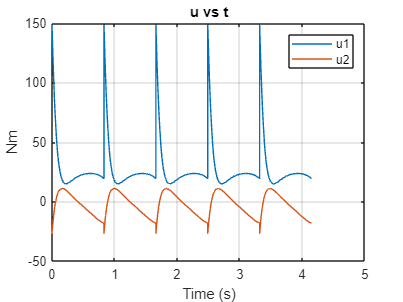

    
% Plot u vs t
% figure ; plot(t_sol, u_sol) ;
%     xlabel('Time (s)') ; ylabel('Nm') ; title('u vs t') ; legend('u1', 'u2') ; grid

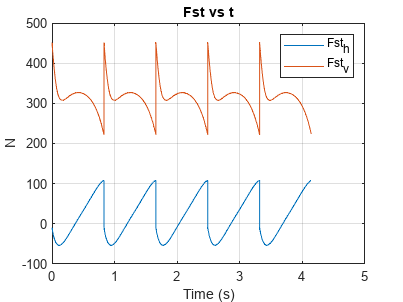

    
% Plot Fst vs t
% figure ; plot(t_sol, FSt_sol) ;
%     xlabel('Time (s)') ; ylabel('N') ; title('Fst vs t') ; legend('Fst_h', 'Fst_v') ; grid

## Problem 2b

We will check the vertical ground reaction force being positive and the ground reaction force being within the friction cone next.

 % Plot Fst_vertical vs t
% figure ; plot(t_sol, FSt_sol(:,2)) ;
%     hold on ; plot(t_sol, zeros(size(t_sol)), 'r--')
%     xlabel('Time (s)') ; ylabel('N') ; title('Fst-vertical vs t') ; grid
 % Plot |Fst_horizontal/Fst_vertical| vs t
% figure ; plot(t_sol, abs(FSt_sol(:,1) ./ FSt_sol(:,2)) ) ;
%     hold on ; plot(t_sol, ones(size(t_sol))*params.mu, 'r--')
%     xlabel('Time (s)') ; title('|Fst-horizontal/Fst-vertical| vs t') ; grid

## Functions

Create Dynamics and Events Function:

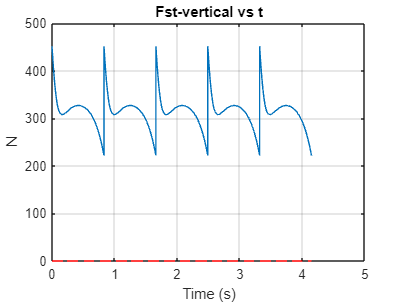

function dx = three_link_dynamics(t, x, params)
    u = three_link_io_control(x, params);

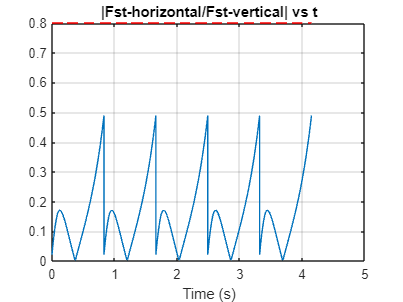

    dx = fvec_gen(x) + gvec_gen(x)*u;
end

% Event function

function [value,isterminal,direction] = three_link_event(t, x, params)
    th = params.T*x(1:5) + params.d;
    value = th(3) - params.th1d;
    isterminal = 1;
    direction = 1; 
end

Create Controller Functions:

% Controller Functions
function ret = phi_a(x1, x2, a)
    ret = x1 + 1/(2-a) * sign(x2) * abs(x2)^(2-a) ;
end

function ret = psi_a(x1, x2, a)
    ret = -sign(x2)*abs(x2)^a - sign(phi_a(x1,x2,a))*abs(phi_a(x1,x2,a))^(a/(2-a)) ;
end

function u = three_link_io_control(x, params)
    y = y_gen(x, params.th3d);
    dy = Lfy_gen(x);
    LgLfy = LgLfy_gen(x);
    Lf2y = Lf2y_gen(x);
    
    y1 = y(1); y2 = y(2);
    dy1 = dy(1); dy2 = dy(2);
    
    e = params.eps;  a = params.a ;
    v = [psi_a(y1, e*dy1, a);
         psi_a(y2, e*dy2, a)]./e^2;
    
    u = inv(LgLfy)*(-Lf2y + v);
end